Observability Test

syms M m1 m2 l1 l2 g
% g = 9.81; 
A = [0 1 0 0 0 0;
     0 0 (-g*m1)/M 0 (-g*m2)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M+m1))/(M*l1) 0 -(g*m2)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(g*m1)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B = [0;
    1/M;
    0;
    1/(M*l1);
    0;
    1/(M*l2)];

C_01 = [1 0 0 0 0 0];

C_02 = [0 0 1 0 0 0;   
    0 0 0 0 1 0];

C_03 = [1 0 0 0 0 0;
    0 0 0 0 1 0];

C_04 = [1 0 0 0 0 0;  
    0 0 1 0 0 0;   
    0 0 0 0 1 0];

D = 0;
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;
A = double(subs(A, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));
B = double(subs(B, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));

Defining K using LQR 

Q = [1000 0 0 0 0 0;  %x penalize
     0 1000 0 0 0 0;  %x_dot penalize
     0 0 1 0 0 0;   %theta1 penalize
     0 0 0 1 0 0;   %theta1_dot penalize
     0 0 0 0 1 0;   %theta2 penalize
     0 0 0 0 0 1];  %theta2_dot penalize
% Q =eye(6)*100;
R = 0.001;
[K,~,~] = lqr(A, B, Q, R);
disp(K);

   1.0e+03 *

    1.0000    1.8191   -0.2725   -0.9704   -0.1740   -0.5649



Defining the system before using the observer

sys1 = ss(A,B,C_01,D);
sys2 = ss(A,B,C_02,D);
sys3 = ss(A,B,C_03,D);
sys4 = ss(A,B,C_04,D);

Finding L

p = [-1; -2; -3; -4; -5; -6];
L1 = place(A',C_01',p)';
disp(L1);

   1.0e+03 *

    0.0210
    0.1734
   -2.9262
    0.0805
    2.2116
   -1.4493



L3 = place(A',C_03',p)';
disp(L3);

   13.0744   -0.8244
   56.2562   -8.4805
  -89.0764   19.7693
  -20.0115   10.9419
    0.3520    7.9256
    3.4793   13.2122



L4 = place(A',C_04',p)';
disp(L4);

    8.5631   -0.8851    0.0000
   17.5219   -4.9484   -0.9810
   -0.9140    9.4369   -0.0000
   -4.1173   20.9385   -0.0491
    0.0000   -0.0000    3.0000
    0.0000   -0.0981    0.9209



Define The A_Cap, B_Cap, C_Cap

A_Cap_1 = [(A-B*K) B*K;
    zeros(size(A)) (A-L1*C_01)];
C_Cap_1 = [C_01 zeros(size(C_01))];

A_Cap_2 = [(A-B*K) B*K;
    zeros(size(A)) (A-L3*C_03)];
C_Cap_2 = [C_03 zeros(size(C_03))];

A_Cap_3 = [(A-B*K) B*K;
    zeros(size(A)) (A-L4*C_04)];
C_Cap_3 = [C_04 zeros(size(C_04))];

B_Cap = [B;zeros(size(B))];

System with Luenberger

sys_1 = ss(A_Cap_1, B_Cap, C_Cap_1, D);
sys_2 = ss(A_Cap_2, B_Cap, C_Cap_2, D);
sys_3 = ss(A_Cap_3, B_Cap, C_Cap_3, D);

Graph Print for all the N

x_0 = [10;0;10;0;20;0;0;0;0;0;0;0];
% Display Plot of x(t)
disp('');
disp('Plot of X(t) when only x(t) is expected and step Graph')

Plot of X(t) when only x(t) is expected and step Graph


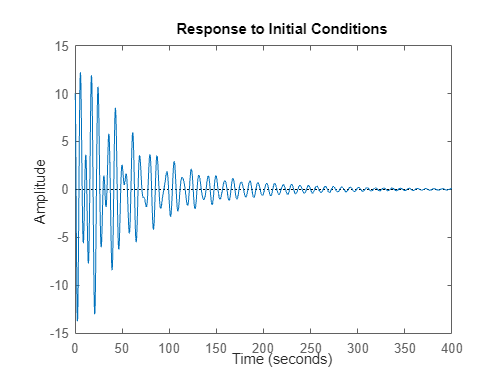

figure 
initial(sys_1,x_0)

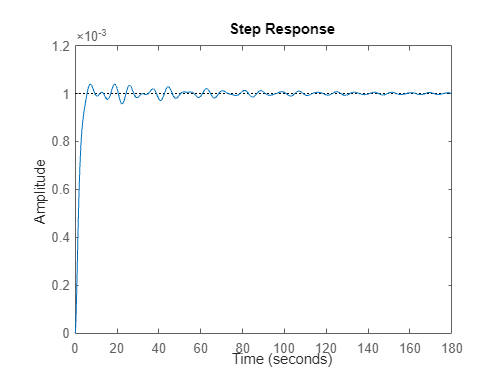

figure
step(sys_1)

disp('')
disp('Plot of X(t) and theta2(t) when only x(t) and theta(2) is expected and step Graph')

Plot of X(t) and theta2(t) when only x(t) and theta(2) is expected and step Graph


figure 
initial(sys_2(1),x_0)

step(sys_2(1))

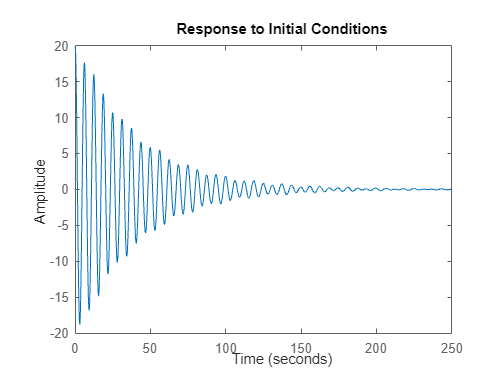

figure 
initial(sys_2(2),x_0)

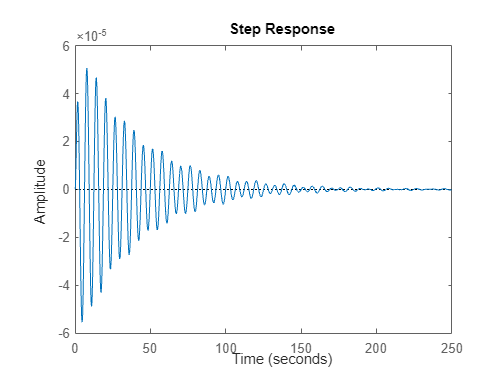

step(sys_2(2))

disp('');
disp('Plot of X(t), theta1(t) and theta2(t) when only x(t), theta1(t) and theta2(t) is expected and step Graph')

Plot of X(t), theta1(t) and theta2(t) when only x(t), theta1(t) and theta2(t) is expected and step Graph


figure 
initial(sys_3(1),x_0)

step(sys_3(1))

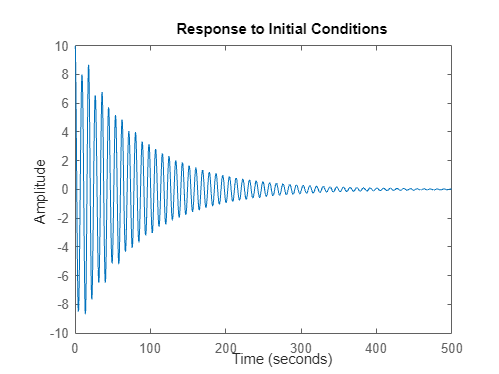

figure 
initial(sys_3(2),x_0)

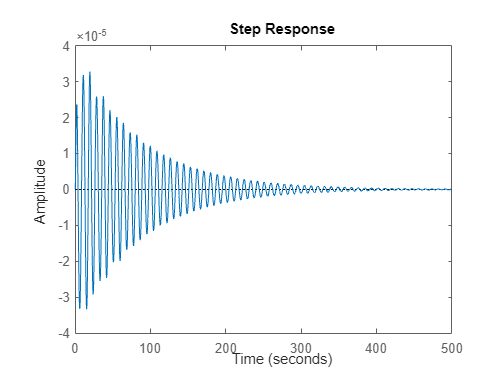

step(sys_3(2))

figure 
initial(sys_3(3),x_0)

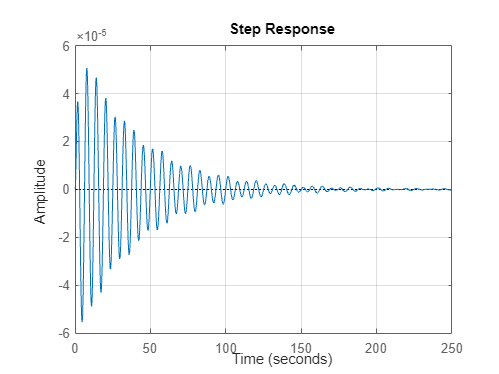

step(sys_3(3))

grid on